Para Ts grande

Diseñamos C para una F buscada

### El mejor control(eficiente):

C(z) con mismo orden en num y denominador

Diferencia de ordenes num y denominador de Dy F iguales

F tiene un polo las que cero

clc 
clear
runTime=2.5; %Tiempo que dura la simulacion de Simulink

### Periodo de Muestreo

Ts=0.05; %buscamos un Ts que haga que Pd sea inversamente estable
ts=Ts;

### Modelo de Planta

%%Modelado
s=tf('s');
z=tf('z', Ts);
Km=8.2897e-02;
Tm= 6.0718e-02;
Tf=0.18;
P = Km/(Tm*s+1)/(Tf*s+1);
Pd=c2d(P, Ts, 'zoh')

Pd =
 
  0.006663 z + 0.004618
  ----------------------
  z^2 - 1.196 z + 0.3325
 
Sample time: 0.05 seconds
Discrete-time transfer function.



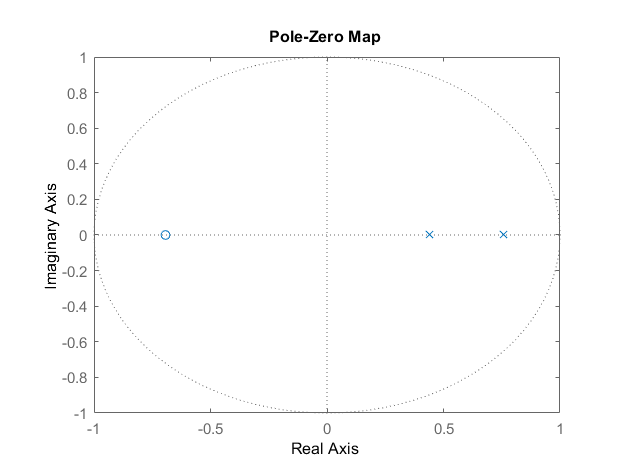

pzmap(Pd)% O dentro del circulo unidad -> estable

En este caso,el denominador tiene 2 polos mas que ceros asi que usaremos un deadbeat de 2º orden como optimo

### Primer Orden: Fd =1/z

Fd=1/z;
% Fd=Cd*Pd/(1+Cd*Pd) ==> Cd=Fd/Pd/(1-Fd)
Cd=minreal(Fd/Pd/(1-Fd));
Crd=Cd;
%PlotSimulation("PrimerOrden","Control_deadbeat_sim.slx")
load v_Velocidad_rampa.mat Velocidad
Velocidad = Velocidad(3500:6029,:)

Velocidad =    18.3000    0.0500         0         0
   18.3050    0.0500         0         0
   18.3100    0.0500         0         0
   18.3150    0.0500         0         0
   18.3200    0.0500         0         0
   18.3250    0.0500         0         0
   18.3300    0.0500         0         0
   18.3350    0.0500         0         0
   18.3400    0.0500         0         0
   18.3450    0.0500         0         0


result =          0
    0.0050
    0.0100
    0.0150
    0.0200
    0.0250
    0.0300
    0.0350
    0.0400
    0.0450


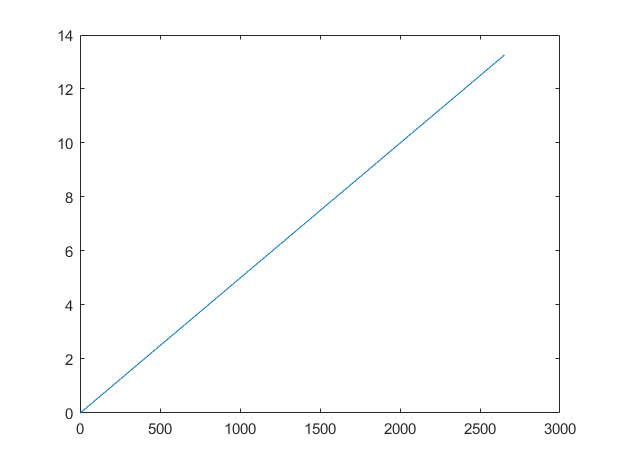

ans =          0
    0.0050
    0.0100
    0.0150
    0.0200
    0.0250
    0.0300
    0.0350
    0.0400
    0.0450


PlotSimulation("SimulacionPrimer","SIM_VELOCIDAD.slx")

Para ordenes mayores que uno añadimos ceros iguales a los ceros de la planta

### Segundo orden Fd= (z −α )/(1−α )/z^2

[zPd,pPd,kPd]=zpkdata(Pd,'v')

zPd = -0.6931

pPd =     0.7575
    0.4389


kPd = 0.0067

alfa=zPd(1);
Fd=(z-alfa)/(1-alfa)/z^2;
% Fd=Cd*Pd/(1+Cd*Pd) ==> Cd=Fd/Pd/(1-Fd)
Cd=minreal(Fd/Pd/(1-Fd));
Crd=Cd

Crd =
 
  88.64 z^2 - 106.1 z + 29.47
  ---------------------------
    z^2 - 0.5906 z - 0.4094
 
Sample time: 0.05 seconds
Discrete-time transfer function.



%PlotSimulation("SegundoOrden","Control_deadbeat_sim.slx")

load v_Velocidad_rampa.mat Velocidad
Velocidad = Velocidad(3500:6029,:)

Velocidad =    18.3000    0.0500         0         0
   18.3050    0.0500         0         0
   18.3100    0.0500         0         0
   18.3150    0.0500         0         0
   18.3200    0.0500         0         0
   18.3250    0.0500         0         0
   18.3300    0.0500         0         0
   18.3350    0.0500         0         0
   18.3400    0.0500         0         0
   18.3450    0.0500         0         0


result =          0
    0.0050
    0.0100
    0.0150
    0.0200
    0.0250
    0.0300
    0.0350
    0.0400
    0.0450


hola =          0
    0.0050
    0.0100
    0.0150
    0.0200
    0.0250
    0.0300
    0.0350
    0.0400
    0.0450


PlotSimulation("SimulacionSegundo","SIM_VELOCIDAD.slx")

### Tercer orden Fd= (z −α1 )(z −α2 )/(1−α1 )/(1−α2 )/z^2

% [zPd,pPd,kPd]=zpkdata(Pd,'v')
% alfa1=zPd(1);
% alfa2=zPd(2);
% Fd=(z-alfa1)*(z-alfa2)/(1-alfa1)/(1-alfa2)/z^2;
% % Fd=Cd*Pd/(1+Cd*Pd) ==> Cd=Fd/Pd/(1-Fd)
% Cd=minreal(Fd/Pd/(1-Fd));
%Crd=Cd
% PlotSimulation("TercerOrden","Control_deadbeat_sim.slx")
